clear

## **Lista de Funções:**

r = @(x) 100*(x(2)-x(1)^2)^2 + (1-x(1))^2;
g = @(x) x(1)*(x(1) + 3)*(x(1) - 3)*(x(1) - 5) + x(2)*(x(2) + 3)*(x(2) - 3)*(x(2) - 5);
f = @(x) ((x(1))^2 - 100)*((x(1))^2 - 61) + ((x(2))^2 - 25)*((x(2))^2 - 16) - 15*cos(x(1)-(7/5))*cos(x(2)-(9/2));
h = @(x) ((x(1))^2 - 100)*((x(1))^2 - 61) + ((x(2))^2 - 25)*((x(2))^2 - 16) - 15*sin(x(1)-(7/5))*sin(x(2)-(9/2));

## Teste 1 - Função matemática g(x)

disp("--------------- Variaveis globais --------------");

--------------- Variaveis globais --------------


Nvar = 2;
Nmax = randi([35,50])

Nmax = 36

errodf = 15e-2

errodf = 0.1500

NPontosIniciais = randi([8,13])

NPontosIniciais = 10

x_values=[-11;-11]; y_values=[7;7];
lambda = 0.0005

lambda = 5.0000e-04


disp("------------------- Outputs -------------------");

------------------- Outputs -------------------


    
PontosIniciais = getNPontosIniciais(NPontosIniciais, Nvar,x_values,y_values);
tic;
[Lista, LNit, Lopt, dffinal] = steepest_descent_static(g, Nmax, errodf, PontosIniciais, x_values, y_values, lambda);
tempo_execucao_teste1 = toc

tempo_execucao_teste1 = 3.0328

xopt_teste1 = minGlobal(Lopt, g)

xopt_teste1 =    -1.6206
   -2.2466


taxa_media_convergencia_teste1 = taxaMediaConvergencia(LNit)

taxa_media_convergencia_teste1 = 36

tipo_convergencia_teste1 = tipoConvergencia(dffinal, errodf, Nmax)

tipo_convergencia_teste1 = 'Convergência para um mínimo local'

[minimos_locais_teste1, minimizantes_locais_teste1] = minimosMinimizantesLocais(Lopt, g)

minimos_locais_teste1 =    -2.2530   -2.2407
   -2.1265   -2.2195


minimizantes_locais_teste1 =  -131.9849 -129.8371


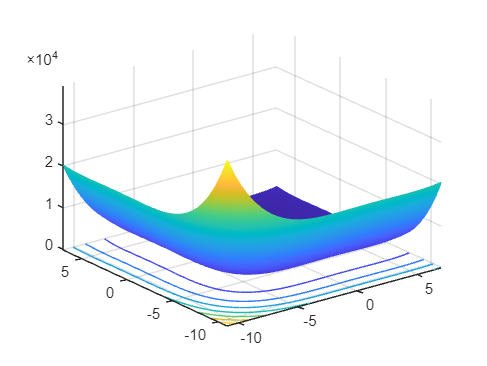

close all

nivelGraficos(g,x_values(1),y_values(1),x_values(2),y_values(2))

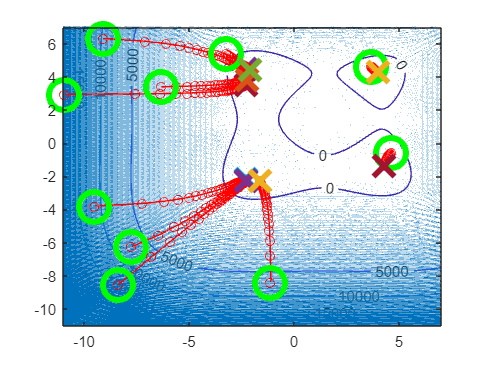


hold on

graficosLineSearch(Lista,LNit,Lopt)

hold off

## Teste 2- Função de Rosenbrock

lambda = 0.000005;
disp("---------------------- // ----------------------")

---------------------- // ----------------------



tic; 
[Lista, LNit, Lopt, dffinal] = steepest_descent_static(r, Nmax, errodf, PontosIniciais, x_values, y_values, lambda);
tempo_execucao_teste2 = toc

tempo_execucao_teste2 = 3.4222

xopt_teste2 = minGlobal(Lopt, r)

xopt_teste2 =    -2.6437
    5.4920


taxa_media_convergencia_teste2 = taxaMediaConvergencia(LNit)

taxa_media_convergencia_teste2 = 36

tipo_convergencia_teste2 = tipoConvergencia(dffinal, errodf, Nmax)

tipo_convergencia_teste2 = 'Convergência para um mínimo local'

[minimos_locais_teste2, minimizantes_locais_teste2] = minimosMinimizantesLocais(Lopt, r)

minimos_locais_teste2 =     2.6655   -2.6437    2.2576
    4.8010    5.4920   -0.2089


minimizantes_locais_teste2 = 1.0e+03 *

    0.5335    0.2374    2.8165


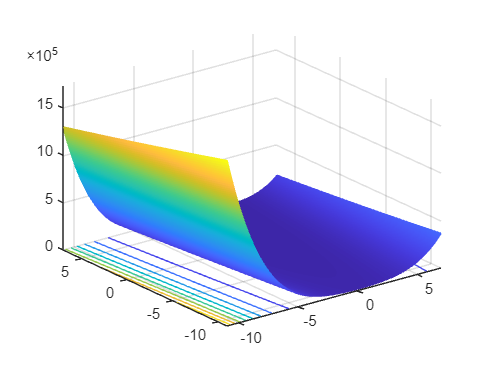

close all

nivelGraficos(r,x_values(1),y_values(1),x_values(2),y_values(2))

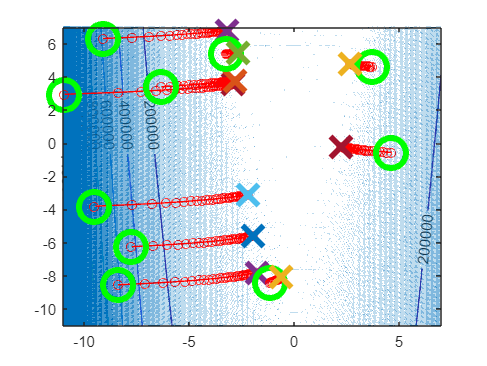


hold on

graficosLineSearch(Lista,LNit,Lopt)

hold off

## Teste 3- Função matemática f(x)

disp("---------------------- // ----------------------")

---------------------- // ----------------------


disp("Nesta funçao consideramos alterar o valor; devido a erros")

Nesta funçao consideramos alterar o valor; devido a erros


lambda = 0.0005;

tic;
[Lista, LNit, Lopt, dffinal] = steepest_descent_static(f, Nmax, errodf, PontosIniciais, x_values, y_values, lambda);
tempo_execucao_teste3 = toc

tempo_execucao_teste3 = 4.0362

xopt_teste3 = minGlobal(Lopt, f)

xopt_teste3 =    -8.9552
   -4.5067


taxa_media_convergencia_teste3 = taxaMediaConvergencia(LNit)

taxa_media_convergencia_teste3 = 36

tipo_convergencia_teste3 = tipoConvergencia(dffinal, errodf, Nmax)

tipo_convergencia_teste3 = 'Convergência para um mínimo local'

[minimos_locais_teste3, minimizantes_locais_teste3] = minimosMinimizantesLocais(Lopt, f)

minimos_locais_teste3 =    -8.9552   -8.9544
   -4.5067   -4.5906


minimizantes_locais_teste3 =  -408.5616 -408.5449


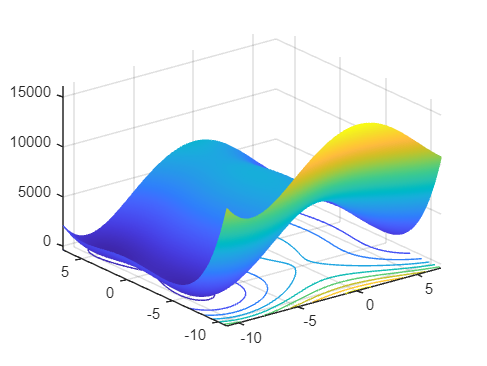

close all

nivelGraficos(f,x_values(1),y_values(1),x_values(2),y_values(2))

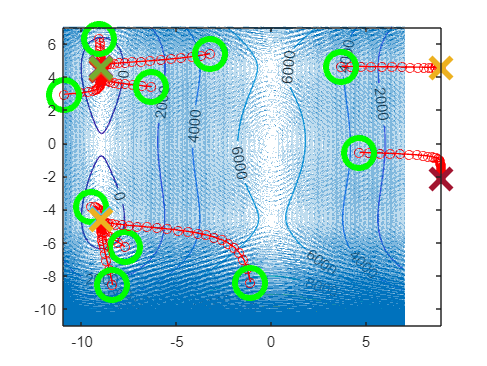


hold on

graficosLineSearch(Lista,LNit,Lopt)

hold off

## Teste 4 - Função matemática h(x,y)

lambda = 0.000005;
disp("---------------------- // ----------------------")

---------------------- // ----------------------



tic;
[Lista, LNit, Lopt, dffinal] = steepest_descent_static(h, Nmax, errodf, PontosIniciais, x_values, y_values, lambda);
tempo_execucao_teste4 = toc

tempo_execucao_teste4 = 4.0211

xopt_teste4 = minGlobal(Lopt, h)

xopt_teste4 =    -9.4214
   -3.8210


taxa_media_convergencia_teste4 = taxaMediaConvergencia(LNit)

taxa_media_convergencia_teste4 = 36

tipo_convergencia_teste4 = tipoConvergencia(dffinal, errodf, Nmax)

tipo_convergencia_teste4 = 'Convergência para um mínimo local'

[minimos_locais_teste4, minimizantes_locais_teste4] = minimosMinimizantesLocais(Lopt, f)

minimos_locais_teste4 =    -9.4214   -7.8378
   -3.8210   -6.1727


minimizantes_locais_teste4 =  -298.5702  268.2350


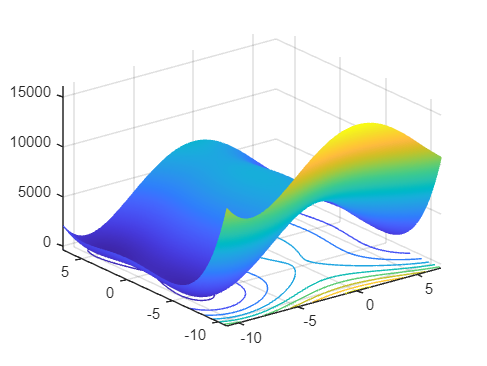

close all

nivelGraficos(h,x_values(1),y_values(1),x_values(2),y_values(2))

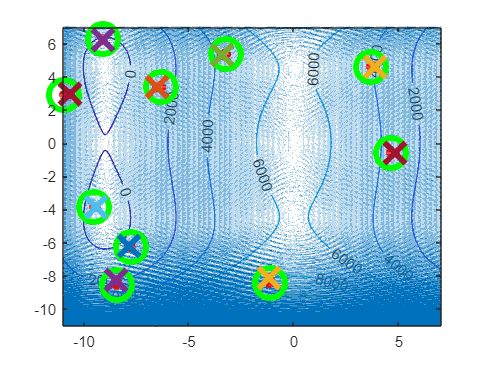


hold on

graficosLineSearch(Lista,LNit,Lopt)

hold off

T = table([tempo_execucao_teste1; tempo_execucao_teste2; tempo_execucao_teste3;tempo_execucao_teste4], ...
          [taxa_media_convergencia_teste1; taxa_media_convergencia_teste2; taxa_media_convergencia_teste3; taxa_media_convergencia_teste4], ...
          {tipo_convergencia_teste1; tipo_convergencia_teste2; tipo_convergencia_teste3; tipo_convergencia_teste4}, ...
          'VariableNames', {'Tempo de Execucao', 'Taxa Media de Convergencia', 'Tipo de Convergencia'}, ...
          'RowNames', {'Teste1', 'Teste2', 'Teste3', 'Teste4'});

disp(T);

              Tempo de Execucao    Taxa Media de Convergencia            Tipo de Convergencia         
              _________________    __________________________    _____________________________________

    Teste1         3.0328                      36                {'Convergência para um mínimo local'}
    Teste2         3.4222                      36                {'Convergência para um mínimo local'}
    Teste3         4.0362                      36                {'Convergência para um mínimo local'}
    Teste4         4.0211                      36                {'Convergência para um mínimo local'}

